**Instituto Politécnico Nacional**

**Unidad Profesional Interdisciplinaria en Ingeniería y Tecnologías Avanzadas**

**Integración de un Sistema Robótico**

# Seguimiento de Trayectoria con Robot Antropomórfico

Equipo 6:

- Fierro De La Rosa Abril Evangelina

- Islas Estrada Luis Rafael

- Luna Reyes Rodrigo

- Montero Rasgado Josué Emiliano

## Robot Puma

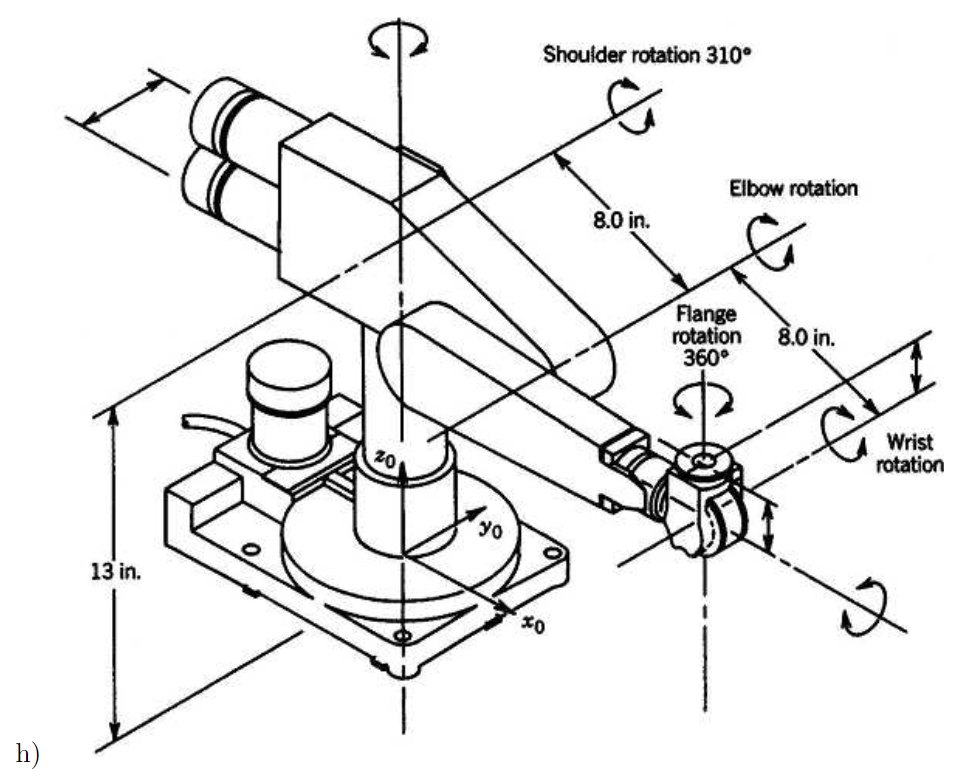

Para comenzar con el proyecto final es necesario retomar algunos conceptos, con los cuáles se nos facilitará la comprensión del proyecto que a continuación se presenta.

## **Cinemática Directa**

El problema de **la cinemática directa** es donde "dadas las variables de las juntas de un robot, determinamos la posición y orientación de nuestro efector final.

En el análisis cinemático, el robot es pensado como un conjunto de cuerpos rígidos conectados entre sí por varias juntas o uniones. El objetivo es determinar el efecto acumulativo del conjunto de variables de las juntas, para esto se presentan de manera sistemática ciertas convenciones, el objetivo de las convenciones es simplificar el análisis, dando lugar a un lenguaje común en el cual los ingenieros pueden comunicarse.

A cada eslabón se le adhiere un marco coordenado, siendo un marco inercial ***s*** la base el cual es el marco $O$, después se escogen los marcos del ***1*** al ***n*** en dónde cada marco coordenado esta rígidamente adherido al marco al eslabón ***i***. Esto significa que sin importar el movimiento del robot las coordenadas de cada punto en el eslabón ***i*** son constantes cuando son expresadas en términos del marco ***i***.

Suponiendo que   es una transformación homogénea de coordenadas

en un punto del marco ***i*** el marco ***i-1***, la matriz **A** no es constante, varía conforme la configuración del robot cambia. La suposición de que todas las juntas pueden ser una combinación entre juntas prismática o de revoluta donde Ai es función de sólo una variable de junta (**qi**):

-  

Para denotar la posición del efector final con respecto al marco inercial (Base) se usa un vector  y una matriz de rotación de  .

- 

Donde   cada transformación homogénea  .

- 

### La representación de Denavit - Hartenberg

## **Cinemática Inversa**

- **Paso 1:** Se asignan los ejes $z_0, z_1, z_2, z_3, z_4, z_5$ como los ejes de rotación de $q_1, q_2, q_3, q_4, q_5, q_6$.

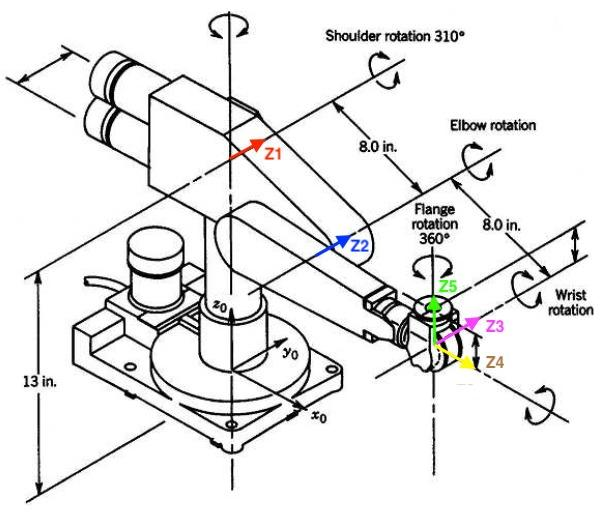

- **Paso 2: **Para el origen $O_0$, se usa la referencia brindada por el diagrama.

- **Pasos 3-5: **Dado que $z_1$ es perpendicular a $z_0$, el marco $O_1$ se coloca en el punto de intersección entre ambos ejes. Para $O_2$ se usa como referencia la distancia física entre los ejes de giro $z_1$ y $z_2$, además de considerar que, dada la anchura de los eslabones, existe una distancia $d_1$ que separa a ambos marcos en dirección de sus ejes $z$. 

- **Paso 6: **Finalmente, dado que los ejes $z_3, z_4, z_5$, son perpendiculares entre sí y se intersectan en el mismo punto se decide colocar un mismo origen $O$ para las tres juntas (sin olvidar las distancias que existen entre las juntas en el diagrama).

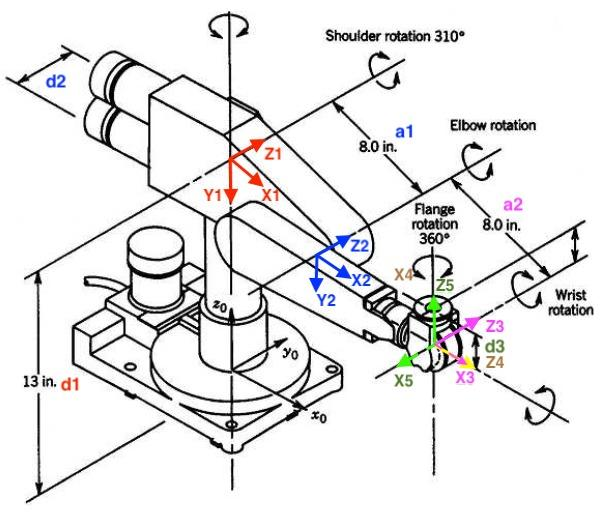

De esta forma, la tabla de parámetros de Denavit Hartenberg queda de la siguiente forma:

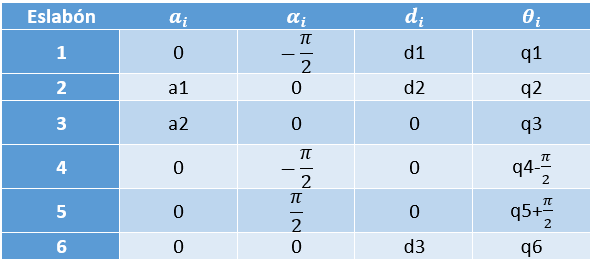

clc; clear; close all;
syms a1 a2 d1 d2 d3 d4 a alpha d theta q1 q2 q3 q4 q5 q6

A(a, alpha, d, theta) = [cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha) a*cos(theta);
    sin(theta) cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);
    0 sin(alpha) cos(alpha) d;
    0 0 0 1]

Por lo que las matrices de transformación quedan así:

A1 = A(0, -pi/2, d1, q1)
A2 = A(a1, 0, d2, q2)
A3 = A(a2, 0, 0, q3)
A4 = A(0, -pi/2, 0, q4-pi/2)
A5 = A(0, pi/2, 0, q5+pi/2)
A6 = A(0, 0, d3, q6)

Multiplicando estas matrices obtenemos la matriz de transfroamción del robot completo $T^0_6$.

T06 = A1*A2*A3*simplify(A4)*simplify(A5)*A6;
R06 = simplify(T06(1:3,1:3),10)
D06 = simplify(T06(1:3,4),10)

## **7.  Robot PUMA 260 con Muñeca Esférica**

### **a) Coordenadas Deseadas del Centro de la Muñeca**

Dado que los orígenes $o_{x_4 y_4 z_4 }$ y $o_{x_5 y_5 z_5 }$ coinciden con $o_c$, entonces se tiene que: 


$$O=O_c +d_6 R\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$$


Por lo tanto: 


$$\left\lbrack \begin{array}{c}
x_c \\
y_c \\
z_c 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
o_x -d_6 r_{13} \\
o_y -d_6 r_{23} \\
o_z -d_6 r_{33} 
\end{array}\right\rbrack$$


Donde $d_6$ es la distancia entre la herramienta ($o_6$) y $o_c$ medida sobre $z_5$

### **b) Posición Inversa**

Tomando las primeras 3 transformaciones del problema 1h: 

clc; clear; close all;
syms theta_1 theta_2 theta_3 a_1 d_1 a_2 d_2
A = @(a, d, al, th) trotz(th)*transl([0, 0, d])*transl([a, 0, 0])*trotx(al); 
A03 = simplify(A(0, d_1, pi/2, theta_1)*A(a_1, d_2, 0, theta_2)*A(a_2, 0, 0, theta_3)) 

Se pueden obtenar la cinemática inversa resolviendo para $\theta_1$, $\theta_2$ y $\theta_3$ el siguiente sistema de ecuaciones:


$$\left\lbrack \begin{array}{c}
A_{14} \\
A_{24} \\
A_{34} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
o_x -d_6 r_{13} \\
o_y -d_6 r_{23} \\
o_z -d_6 r_{33} 
\end{array}\right\rbrack$$


Sin embargo, resulta muy complicado resolver este sistema de ecuaciones, por lo que un enfoque geométrico es más práctico. 

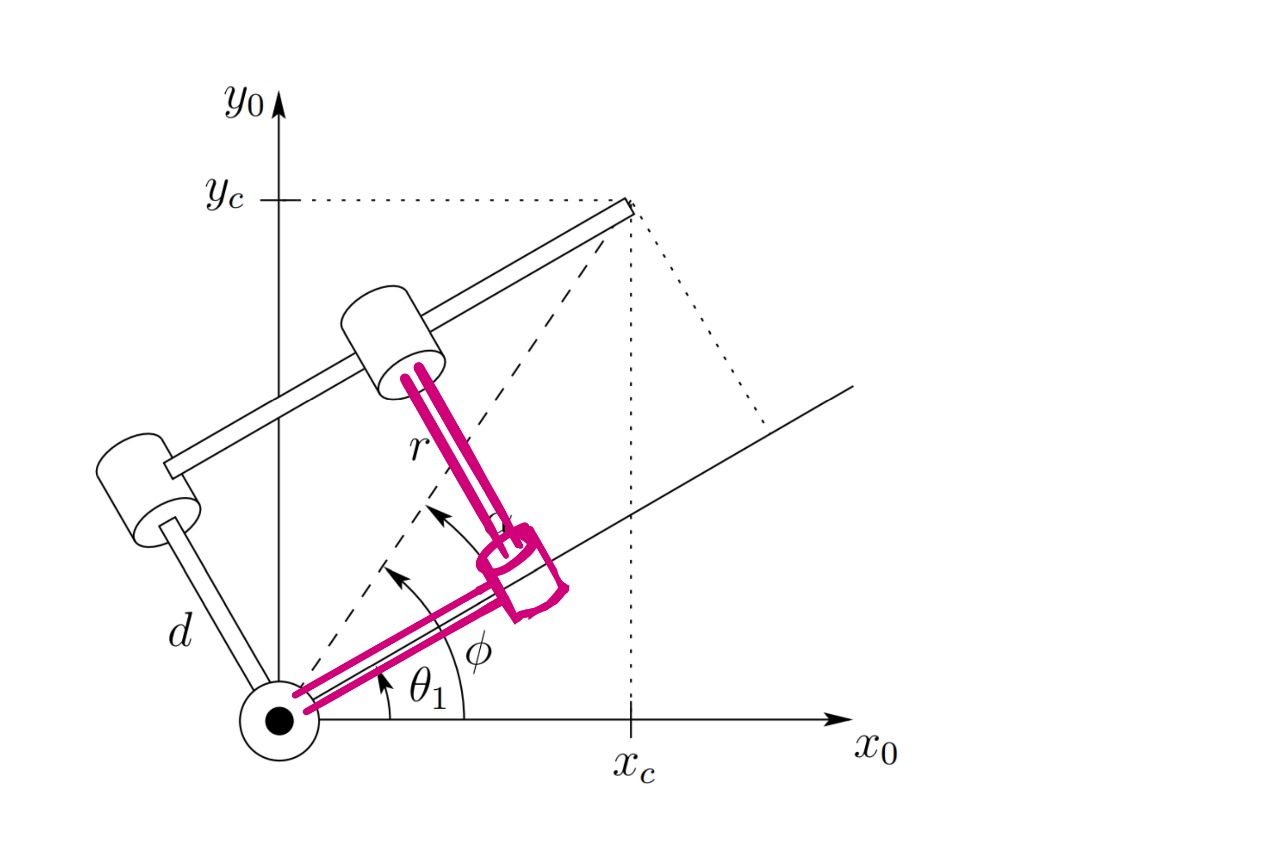

En realidad, el robot PUMA que se incluye en este ejercicio tiene dos codos. Sin embargo, como se ve geometricamente, los resultados son los mismos, podría considerarse que el codo está entre la segunda y la tercera junta o que se encuentran ambos codos y sólo importaría conocer la longitud total que suman ambos codos. 

Cuando se proyecta sobre el plano $x_0 -y_0$ se obtiene lo siguiente:


$$\theta_1 =\phi -\alpha =\textrm{atan2}\left(x_c ,y_c \right)-\textrm{atan2}\left(\sqrt{r^2 -d_2^2 },d_2 \right)=\textrm{atan2}\left(x_c ,y_c \right)-\textrm{atan2}\left(\sqrt{x_c^2 +y_c^2 -d_2^2 },d_2 \right)$$


Con $x_c =o_x -d_6 r_{13}$, $y_c =o_y -d_6 r_{23}$ y $d_2$ es la longitud que suman ambos codos. 

No obstante, la siguiente también es una solución:

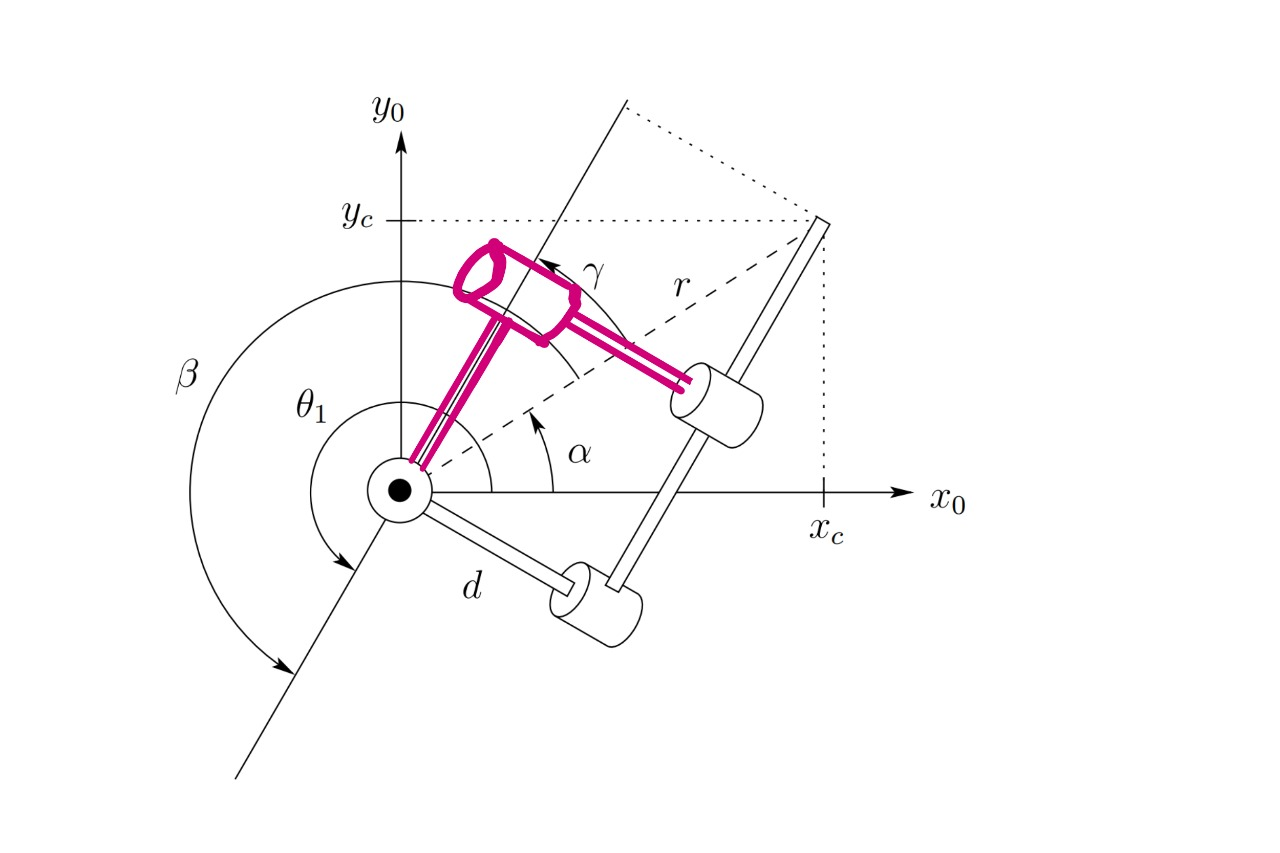


$$\theta_1 =\beta +\alpha =\pi +\gamma +\alpha =\pi +\textrm{atan2}\left(x_c ,y_c \right)+\textrm{atan2}\left(\sqrt{x_c^2 +y_c^2 -d_2^2 },d_2 \right)=\textrm{atan2}\left(x_c ,y_c \right)++\textrm{atan2}\left(-\sqrt{x_c^2 +y_c^2 -d_2^2 },-d_2 \right)$$


Proyectando sobre el plano formado por las juntas 2 y 3

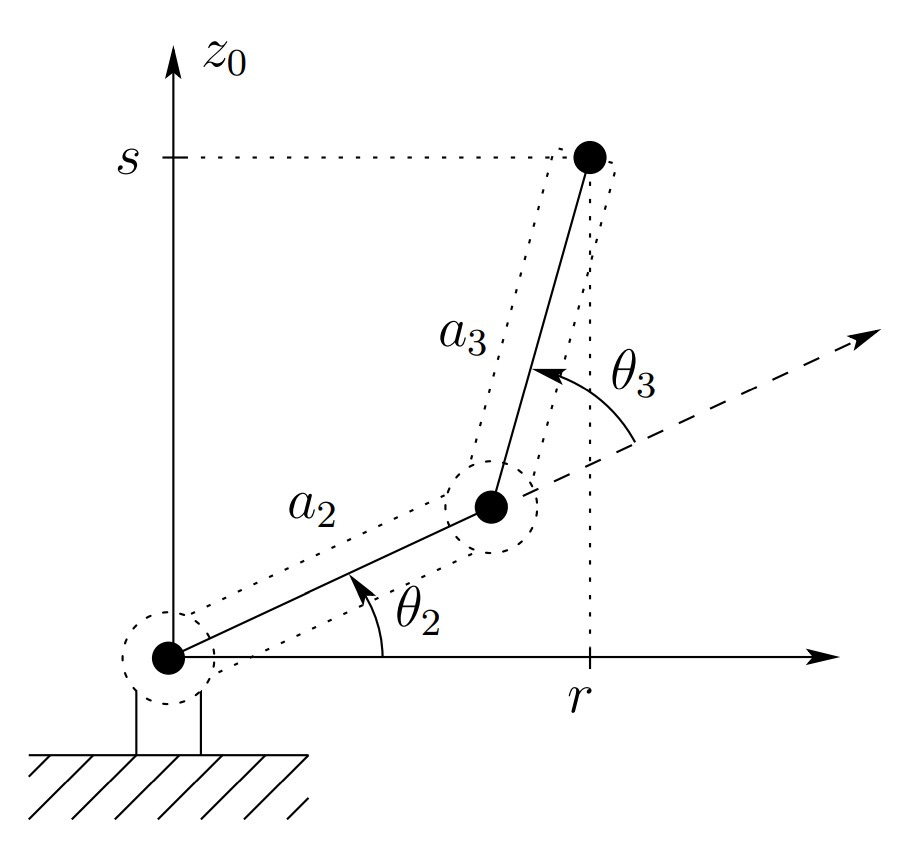

Usando la ley de cosenos:


$$a_2^2 +a_3^2 -2a_2 a_3 \cos \left(\pi -\theta_3 \right)=s^2 +r^2$$



$$a_2^2 +a_3^2 +2a_2 a_3 \cos \left(\theta_3 \right)={\left(z_c -d_1 \right)}^2 +x_c^2 +y_c^2 -d_2^2$$


Entonces


$$c_3 =\cos \left(\theta_3 \right)=\frac{{\left(z_c -d_1 \right)}^2 +x_c^2 +y_c^2 -d_2^2 -a_2^2 -a_3^2 }{2a_2 a_3 }$$


Por lo tanto, 


$$\theta_3 =\textrm{atan2}\left(c_3 ,\pm \sqrt{1-c_3^2 }\right)$$


Con ${z_c =o}_z -d_6 r_{33}$ y $d_1$la distancia entre la junta 1 y el suelo medido sobre $z_0$.

Por último, 


$$\theta_2 =\textrm{atan2}\left(r,s\right)-\textrm{atan2}\left(a_2 +a_3 \cos \left(\theta_3 \right),a_3 \sin \left(\theta_3 \right)\right)=\textrm{atan2}\left(\sqrt{x_c^2 +y_c^2 -d_2^2 },z_c -d_1 \right)-\textrm{atan2}\left(a_2 +a_3 \cos \left(\theta_3 \right),a_3 \sin \left(\theta_3 \right)\right)$$


En total se tienen dos pares de soluciones de $\theta_2$ y $\theta_3$, y 2 soluciones independientes de $\theta_1$. Entonces, el problema de cinemática inversa de la posición de $o_c$ del manipulador PUMA tiene 4 soluciones diferentes. 

### **c) Orientación Inversa**

Para resolver el problema de cinemática inversa de orientación partimos de que conocemos la orientación $R$ de la muñeca esférica y que ya se han determinado 3 de las 6 variables que tiene un manipulador PUMA con muñeca esférica. Entonces:


$$R=R_3^0 R_6^3$$


Donde $R_3^0$ se determina evaluando $A_1 A_2 A_3$ con $\;\theta_1$, $\;\theta_2$ y $\theta_3$. 

R03=A03(1:3, 1:3)

Por lo tanto, 


$$R_6^3 ={\left(R_3^0 \right)}^T R=$$


syms r11 r12 r13 r21 r22 r23 r31 r32 r33
R36= simplify(R03.'*[r11, r12, r13; r21, r22, r23; r31, r32, r33])

Y la matriz de ángulos de euler está dada:

syms theta_4 theta_5 theta_6 
H = trotz(theta_4)*troty(theta_5)*trotz(theta_6); 
Eu = H(1:3, 1:3)

Ambas matrices representan la misma rotación, entonces es posible determinar los ángulos $\theta_4$, $\theta_5$ y $\theta_6$ para los siguientes casos: 

- Si ${\left(R_6^3 \right)}_{13}$ y ${\left(R_6^3 \right)}_{23}$ son distintos de cero, entonces $\sin \left(\theta_5 \right)\not= 0$ y los ángulos pueden determinarse de la  siguiente forma:


$$c_5 =\cos \left(\theta_5 \right)=r_{13} \sin \left(\theta_1 \right)-r_{23} \cos \left(\theta_1 \right)$$


Por lo tanto: 


$$\theta_5 =\textrm{atan2}\left(\textrm{c5},\pm \sqrt{1-c_5^2 }\right)=\textrm{atan2}\left(r_{13} \sin \left(\theta_1 \right)-r_{23} \cos \left(\theta_1 \right),\pm \sqrt{1-{\left(r_{13} \sin \left(\theta_1 \right)-r_{23} \cos \left(\theta_1 \right)\right)}^2 }\right)$$


               a). Si se toma la solución donde $\pm$ es $+$, se tiene que $\sin \left(\theta_5 \right)>0$ y:


$$\theta_4 =\textrm{atan2}\left(\cos \left(\theta_4 \right)\sin \left(\theta_5 \right),\sin \left(\theta_4 \right)\sin \left(\theta_5 \right)\right)=\textrm{atan2}\left(r_{33} s_{23} +r_{13} c_{23} c_1 +r_{23} c_{23} s_1 ,r_{33} c_{23} -r_{13} s_{23} c_1 -r_{23} s_{23} s_1 \right)$$



$$\theta_6 =\textrm{atan2}\left(\cos \left(\theta_6 \right)\sin \left(\theta_5 \right),\sin \left(\theta_6 \right)\sin \left(\theta_5 \right)\right)=\textrm{atan2}\left(r_{21} c_1 -r_{11} s_1 ,r_{12} s_1 -r_{22} c_1 \right)$$


               b). Si se toma la solución donde $\pm$ es $-$, se tiene que $\sin \left(\theta_5 \right)<0$. Por lo tanto:


$$\theta_4 =\textrm{atan2}\left(-\cos \left(\theta_4 \right)\sin \left(\theta_5 \right),-\sin \left(\theta_4 \right)\sin \left(\theta_5 \right)\right)=\textrm{atan2}\left(-r_{33} s_{23} -r_{13} c_{23} c_1 -r_{23} c_{23} s_1 ,-r_{33} c_{23} +r_{13} s_{23} c_1 +r_{23} s_{23} s_1 \right)$$



$$\theta_6 =\textrm{atan2}\left(-\cos \left(\theta_6 \right)\sin \left(\theta_5 \right),-\sin \left(\theta_6 \right)\sin \left(\theta_5 \right)\right)=\textrm{atan2}\left(r_{11} s_1 {-r}_{21} c_1 ,r_{22} c_1 -r_{12} s_1 \right)$$


            2. Si ${\left(R_6^3 \right)}_{13}$ y ${\left(R_6^3 \right)}_{23}$ son iguales a cero, entonces $\sin \left(\theta_5 \right)=0$. Como $R_6^3$ es ortogonal, entonces $\cos \left(\theta_5 \right)=\pm 1$. En este caso no se pueden obtener soluciones para los 3 ángulos. Se parte de que se tienen dos soluciones para $\theta_5$: 

- Si ${\left(R_6^3 \right)}_{33} =r_{13} \sin \left(\theta_1 \right)-r_{23} \cos \left(\theta_1 \right)=1$, entonces $\theta_5 =0$

En este caso ${\left(R_6^3 \right)}_{11} =\cos \left(\theta_4 +\theta_6 \right)$ y ${\left(R_6^3 \right)}_{21} =\sin \left(\theta_4 +\theta_6 \right)$, por lo tanto: 


$$\theta_4 +\theta_6 =\textrm{atan2}\left({\left(R_6^3 \right)}_{11} ,{\left(R_6^3 \right)}_{21} \right)=\textrm{atan2}\left(r_{31} s_{23} +r_{11} c_{23} c_1 +r_{21} c_{23} s_1 ,r_{31} c_{23} -r_{11} s_{23} c_1 -r_{21} s_{23} s_1 \right)$$


- Si ${\left(R_6^3 \right)}_{33} =r_{13} \sin \left(\theta_1 \right)-r_{23} \cos \left(\theta_1 \right)=-1$, entonces $\theta_5 =\pi$

Para este caso, ${\left(R_6^3 \right)}_{11} =-\cos \left(\theta_4 -\theta_6 \right)$ y ${\left(R_6^3 \right)}_{21} =\sin \left(\theta_4 -\theta_6 \right)$. Por lo tanto: 


$$\theta_4 -\theta_6 =\textrm{atan2}\left({-\left(R_6^3 \right)}_{11} ,{\left(R_6^3 \right)}_{21} \right)=\textrm{atan2}\left(-r_{31} s_{23} -r_{11} c_{23} c_1 -r_{21} c_{23} s_1 ,r_{31} c_{23} -r_{11} s_{23} c_1 -r_{21} s_{23} s_1 \right)$$


**Concluyendo**

Existen 4 soluciones distintas de la terna ($\theta_1$, $\theta_2$, $\theta_3$). Conociendo la posición de la herramienta y su orientación, y por la forma del robot, se sabe que estas 4 soluciones son indenpendientes de ($\theta_4$, $\theta_5$, $\theta_6$)  la cual tiene dos soluciones diferentes mientras no haya una singularidad ($\sin \left(\theta_5 \right)=0$). Entonces, cuando no hay singularidades, existen 8 soluciones diferentes. Por otro lado, cuando hay una singularidad, la cantidad de soluciones para $\theta_4$ y $\theta_6$ es infinita. En este caso se recomienda tomar un valor arbitrario de $\theta_4$ y después calcular $\theta_6$. 